# INTERPOLACJA

## Rzeczywista transformata Fouriera

Na początek wyjaśnijmy pewną terminologię.

1. Interpolacją trygonometryczną szeregiem Fouriera nazywamy interpolację następującymi funkcjami:


$$\begin{array}{l}
b_0 =0\\
b_k =\mathrm{sin}\left(\frac{2\pi k}{N}x\right),\;b_{k+1} =\mathrm{cos}\left(\frac{2\pi k}{N}x\right)
\end{array}$$


W tym momencie położenie węzłów i odległość między węzłami mogą być dowolne. Niezależnie od tego jakie będą możemy zapisać macierz interpolacyjną i ją rozwiązać (patrz ćwiczenie 7). Dodatkowo z członów nie budujemy żadnego wyrażenia.

2. Podstawą rzeczywistej transformaty Fouriera jest ta sama baza funkcji interpolujących, ale rozdzielona na widmo "rzeczywiste" $X_R$ i "urojone" $X_I$ tworząca następujące wyrażenie. 


$$x\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{N}{2}} \left(X_R \left\lbrack k\right\rbrack \cos \left(\frac{2\pi \textrm{kn}}{N}\right)-X_I \left\lbrack k\right\rbrack \sin \left(\frac{2\pi \textrm{kn}}{N}\right)\right)$$


Zwróć uwagę, że:

- rzeczywista transformata Fouriera powstaje z interpolacji szeregiem Fouriera (interpolacji trygonometrycznej) poprzez objęcie członów "rzeczywistych" i "urojonych" wg częstotliwości i zsumowaniu tych różnic razem. Zatem aby wyznaczyć taką transformatę należy wykonać najpierw interpolację.

- powyższa formuła to dokładnie to co zapisaliśmy w p.1 bo: . Dlatego też w rzeczywistym DFT składową stałą zaliczamy do widma "rzeczywistego" . 

- W tych wzorach znika nam "x". To dlatego, że w przetwarzaniu sygnałów uniezależniamy wynik transformaty od osi OX i posługujemy się wyłącznie indeksami próbki. Z punktu widzenia matematycznego oznacza to, że sama transformata DFT interpoluje funkcję trochę inną niż rzeczywista - taką w której jednostki węzłów w osi OX zostały zastąpione ich indeksami. Przypisanie wyniku do konkretnych częstotliwości robimy na sam koniec obliczeń i zależny on jest od częstotliwości próbkowania. **Oznacza to, że Rzeczywista Dyskretna Transformata Fouriera wymaga podania jej jako dane wejściowe próbek uzyskanych ze stałym krokiem h - czyli równomiernie rozłożonych na przedziale [a,b], ze stałą częstotliwością próbkowania. **

% W przetwarzaniu sygnałów zamiast podawania danych wejściowych do
% transformaty rzeczywistej musimy uniezależnić je od osi OX. 
% W rzeczywistych systemach akwizycji danych, które działają ze stałą
% częstotliwość fs dzieje się to naturalnie - do transformaty podawany jest
% to po prostu wektor zebranych próbek.

% Jeżeli jednak chcemy wygenerować przebieg testowi sami, to musimy
% zasymulować takie działanie

% 1. ustalamy częstotliwość próbkowania:
fs=100e3;   % [Hz]

% 2. Ustalamy przedział interpolacji - nazywany w przetwarzaniu sygnałów
% oknem obserwacji - niech u nas próbki będą zbierane przez 3 s. Zatem
% przedział interpolacji to [0,3] s
tmin = 0;
tmax = 3; % [s]

% Ponieważ wygodnie jest przyjąć, że próbkowanie zaczęliśmy w chwili 0 to
% zazwyczaj już tego nie piszemy. Oczywiście moglibyśmy przyjąć dowolny
% przedział np. [1,4], czy [5,8], ale warto trzymać się przyjętych ogólnie
% standardowych konwencji

Zwróć uwagę, że z punktu widzenia interpolacji i generacji sygnałów ma to duże znaczenie. Jednak w rzeczywistości sygnały nie są generowane w komputerze i pochodzą z zewnętrznych źródeł. Przykładowo nadajnika radiowego "nie obchodzi" jakie liczby przypisaliśmy do osi OX - to my po stronie odbiornika musimy przypisać tym próbkom jakieś liczby, żeby stworzyć funkcję, którą będziemy interpolować. Dlatego przyjęło się przypisywać liczby rozpoczynając od zera co oznacza po prostu początek procesu próbkowania.

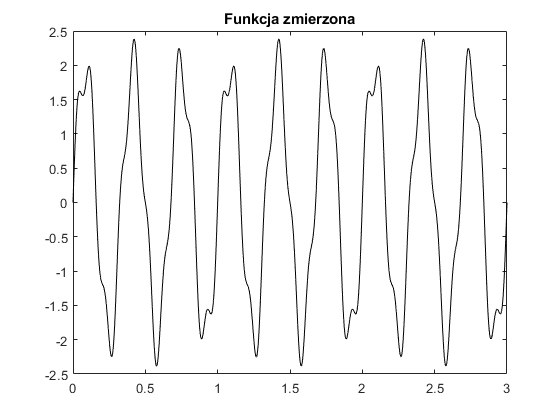

% 3. Posługując się powyższą logiką wygenerujemy sobie najpierw wektor
% położeń próbek na osi OX:
t=[0:1/fs:3-1/fs]; % Zwróć uwagę, że próbki muszą być rozłożone równomiernie (dokładnie 300000 próbek, jak w wersji Python)

% 4. W naszym przykładzie wygenerujemy sygnał - czyli wartości OY punktów w
% węzłach używając powyższych próbek. Ale moglibyśmy je wygenerować
% zupełnie dowolnie zgodnie z powyższą uwagą:
f=@(x) 2.*sin(2*pi*3*t) + 0.4*sin(2*pi*10*t); %Suma sin 3 Hz i 10 Hz
%f=@(x) sawtooth(2*pi*5*t); % Przebieg piłokształtny 5 Hz
warning off;
y = f(t);

% Do policzenia transformaty Fouriera podajemy tylko wektor próbek y
% (ponieważ standardowo interpolowana będzie funkcja y(index x):
[~, m_real] = real_DFT(y);

% Wyrysujmy to na wykresie:

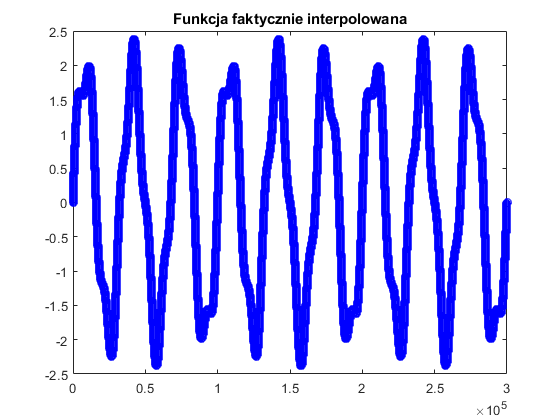

figure(1);
plot(t,y,'k'); title("Funkcja zmierzona");

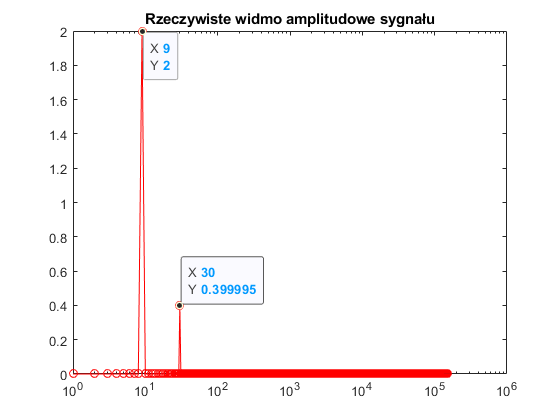

figure(2);
plot([0:1:numel(t)-1],y,'ob'); title("Funkcja faktycznie interpolowana");
figure(3);
[f,real_dft]=real_DFT(y);
pl=semilogx(f, real_dft,'r-o'); title("Rzeczywiste widmo amplitudowe sygnału");hold on;
nonZeroYInd = find(real_dft>1e-1);
y_tip = real_dft(nonZeroYInd);
x_tip = f(nonZeroYInd);
dt1 = datatip(pl,x_tip(1),y_tip(1));

dt2 = datatip(pl,x_tip(2),y_tip(2));
hold off;

warning on;

 

Zwróć uwagę, że **w przypadku widma rzeczywistego widmo amplitudowe jest dokładnie równe amplitudzie danej składowej (dokładniej patrz dalej)**. Przykładowo dla sumy dwóch sinusów uzyskujemy tylko dwie niezerowe próbki o wartościach dokładnie równych amplitudom składowych. Jest to oczywiste jeżeli weźmiemy pod uwagę, że uzyskane przez nas wartości są to po prostu współczynniki interpolacji, a skoro tak i funkcja wejściowa na charakter taki sam jak baza interpolacyjna (sin(x)) to wartości odpowiednich współczynników musza być równe amplitudom sygnałów z definicji problemu interpolacji.

Druga istotna sprawa to to, że w wyniku nie mamy na osi OX częstotliwości tylko numer próbki widma. Pamiętając, że opieramy się na interpolacji można wyliczyć, że **odległość między próbkami ****widma rzeczywistego**** możemy wyliczyć jako fs/N**. I tak dla fs=100kHz i 300001 próbek odległość między próbkami wynosi ~0.3333 Hz. Zatem 9 próbka widma odpowiada częstotliwości $9*0\ldotp 3333\textrm{Hz}=3\;\textrm{Hz}$ - i jak widzimy jej amplituda wynosi 2. Zgadza się to z  amplitudą sygnału wejściowego. Podobnie dla 30 próbki widma $30*0\ldotp 3333\textrm{Hz}=10\;\textrm{Hz}$.

Parę uwag praktycznych:

- odległość między częstotliwościami w widmie zależy od częstotliwości próbkowania i ilość próbek. Im więcej mamy próbek tym jest mniejsza. Dlatego aby zwiększyć dokładność analizy typowo stosuje się bardzo duże ilości próbek. Np. dla pliku mp3 typowa częstotliwość próbkowania wynosi 44.1 kHz. Czyli na każdą analizowaną sekundę pliku audio mamy 44100 próbek. A to tylko popularny format dźwięku, a nie specjalistyczny sprzęt. To oczywiście prowadziłoby do bardzo dużych macierzy interpolacyjnych i w konsekwencji niewydajnych metod rozwiązywania takich układów równań (oraz możliwe, że źle uwarunkowanych). Jak poznamy dalej jest to bezpośredni powód stosowanie transformaty zespolonej.

- maksymalna detekowana częstotliwość zależy z kolei od częstotliwości próbkowania fs. Jest równa jej połowie. Z matematycznego punktu widzenia wynika to wprost z przyjętej bazy interpolacyjnej (indeksacja od 0 do N/2 parami o tej samej częstotliwości). W przetwarzaniu sygnałów nazywa się to częstotliwością graniczną, albo częstotliwością Nyquista. 

- Wyświetlamy sobie wartość widma amplitudowego. Dla rzeczywistej transformaty DFT zapisanego wzorem:

                
$$A=\sqrt{X_R^2 +X_I^2 }$$


które jest wartością średniokwadratową współczynników jednego "członu" równania o tej samej częstotliwości (pulsacji):

            
$$x\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{N}{2}} \left(X_R \left\lbrack k\right\rbrack \cos \left(\frac{2\pi \textrm{kn}}{N}\right)-X_I \left\lbrack k\right\rbrack \sin \left(\frac{2\pi \textrm{kn}}{N}\right)\right)$$


dopóki istnieje tylko składowa "rzeczywista" lub tylko składowa "urojona" widmo interpretuje się łatwo - tak jak jest to zrobione powyżej. Sprawa się komplikuje, kiedy występują obie składowe, np.

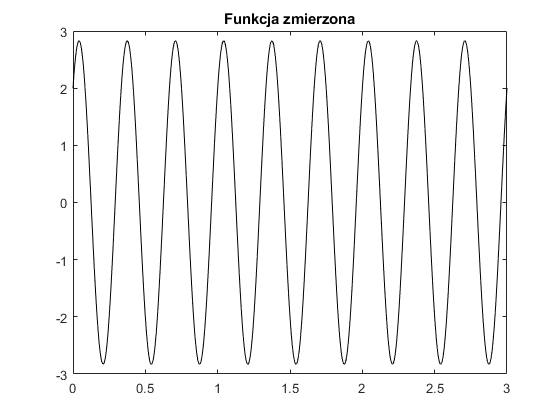

f=@(x) 2.*cos(2*pi*3*t)+2.*sin(2*pi*3*t);
warning off;
y = f(t);

% Do policzenia transformaty Fouriera podajemy tylko wektor próbek y
% (ponieważ standardowo interpolowana będzie funkcja y(index x):
[~, m_real] = real_DFT(y);

% Wyrysujmy to na wykresie:

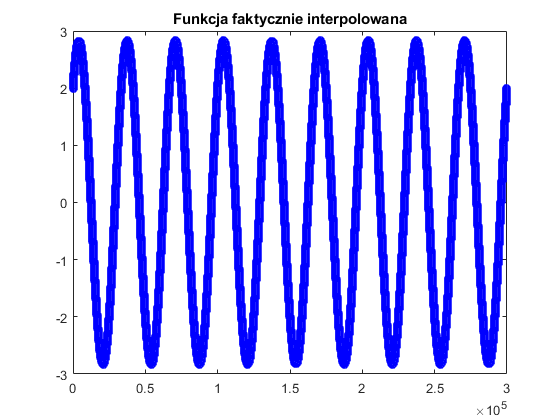

figure(1);
plot(t,y,'k'); title("Funkcja zmierzona");

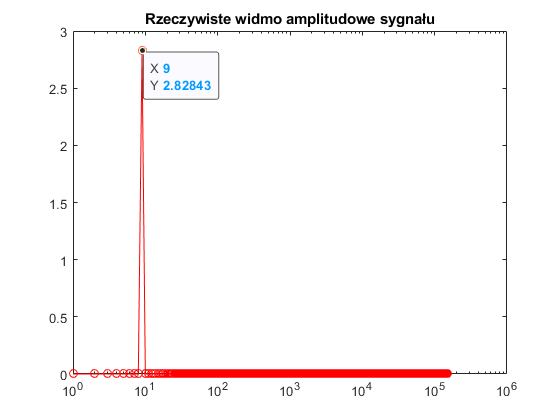

figure(2);
plot([0:1:numel(t)-1],y,'ob'); title("Funkcja faktycznie interpolowana");
figure(3);
[f,real_dft]=real_DFT(y);
pl=semilogx(f, real_dft,'r-o'); title("Rzeczywiste widmo amplitudowe sygnału");hold on;
nonZeroYInd = find(real_dft>1e-1);
y_tip = real_dft(nonZeroYInd);
x_tip = f(nonZeroYInd);

dt1 = datatip(pl,x_tip(1),y_tip(1));
hold off;

warning on;
 

Amplituda widma dla 3 Hz nie jest równa sumie obu amplitud. Do prawidłowej interpretacji potrzebowalibyśmy jeszcze widma fazowego. Z punktu widzenia matematycznego obliczania DFT jako interpolacji nie ma to jednak większego znaczenia - różnica polega wyłącznie na tym co wyświetlamy jako istotną wartość.

- rzeczywiste widmo DFT jest po prostu próbką widma ciągłego (ciągłej transformaty Fouriera) dla danego przebiegu obliczoną w pewnych częstotliwościach.

**WYKROZYSTYWANE FUNKCJE**

function [f,m_real] = real_DFT(y)
    X=fft(y);
    m = abs(X); p = unwrap(angle(X));
    m = abs(m/numel(y));
    m_real = m(1:numel(y)/2+1);
    m_real(2:end-1) = 2*m_real(2:end-1);
    f=[0:1:floor(numel(y)/2)];
end
